# **Newton's 2nd Law model:**   3-dof Spring Mass Damper system

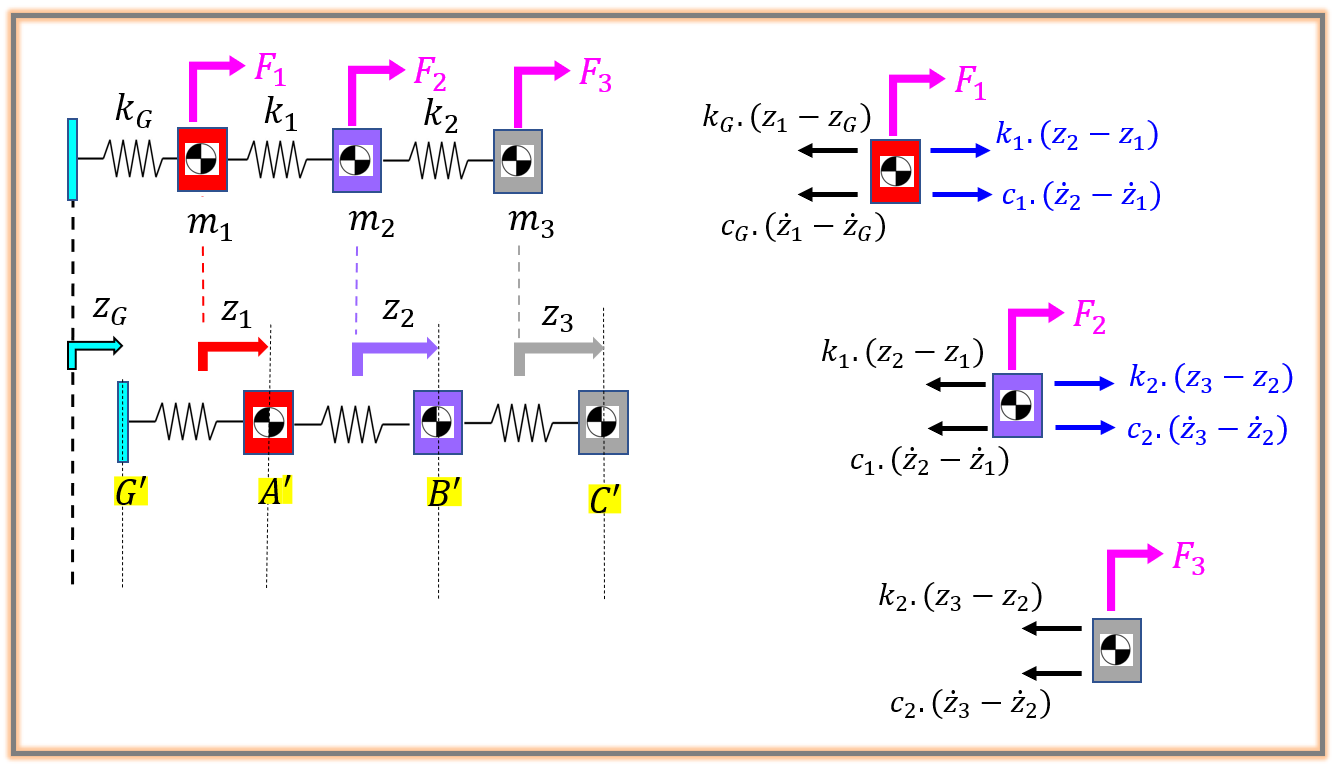

Newton's 2nd Law:   $m\ldotp a=\sum F_i$

- 
$$m\ldotp {\ddot{z} }_1 \;\;=\;F_1 \;-\;k_G \ldotp \left(z_1 -z_G \right)\;\;-\;\;c_G \ldotp \left({\dot{z} }_1 -{\dot{z} }_G \right)\;\;\;+\;\;\;k_1 \ldotp \left(z_2 -z_1 \right)\;\;+\;\;c_1 \ldotp \left({\dot{z} }_2 -{\dot{z} }_1 \right)$$


- 
$$m\ldotp {\ddot{z} }_2 \;\;=\;F_2 \;-\;k_1 \ldotp \left(z_2 -z_1 \right)\;\;\;\;-\;\;c_1 \ldotp \left({\dot{z} }_2 -{\dot{z} }_1 \right)\;\;\;\;+\;\;\;k_2 \ldotp \left(z_3 -z_2 \right)\;\;+\;\;c_2 \ldotp \left({\dot{z} }_3 -{\dot{z} }_2 \right)$$


- 
$$m\ldotp {\ddot{z} }_3 \;\;=\;F_3 \;-\;k_2 \ldotp \left(z_3 -z_2 \right)\;\;\;\;-\;\;c_2 \ldotp \left({\dot{z} }_3 -{\dot{z} }_2 \right)\;\;\;\;$$


Which rearranging gives us:

- 
$$m\ldotp {\ddot{z} }_1 \;\;+\;k_G \ldotp \left(z_1 -z_G \right)\;\;+\;c_G \ldotp \left({\dot{z} }_1 -{\dot{z} }_G \right)\;\;\;-\;\;k_1 \ldotp \left(z_2 -z_1 \right)\;\;-\;c_1 \ldotp \left({\dot{z} }_2 -{\dot{z} }_1 \right)=F_1$$


- 
$$m\ldotp {\ddot{z} }_2 \;\;+\;k_1 \ldotp \left(z_2 -z_1 \right)\;\;\;\;+\;c_1 \ldotp \left({\dot{z} }_2 -{\dot{z} }_1 \right)\;\;\;\;-\;\;k_2 \ldotp \left(z_3 -z_2 \right)\;\;-\;c_2 \ldotp \left({\dot{z} }_3 -{\dot{z} }_2 \right)=F_2$$


- 
$$m\ldotp {\ddot{z} }_3 \;+\;k_2 \ldotp \left(z_3 -z_2 \right)\;\;\;\;+\;c_2 \ldotp \left({\dot{z} }_3 -{\dot{z} }_2 \right)=F_3$$


Which in Matrix form is:

- 
$$\left\lbrack \begin{array}{ccc}
m_1  & \bullet  & \bullet \\
\bullet  & m_2  & \bullet \\
\bullet  & \bullet  & m_3 
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
{\ddot{z} }_1 \\
{\ddot{z} }_2 \\
{\ddot{z} }_3 
\end{array}\right\rbrack \;\;+\left\lbrack \begin{array}{ccc}
\left(c_G +c_1 \right) & \left(-c_1 \right) & \bullet \\
\left(-c_1 \right) & \left(c_1 +c_2 \right) & \left(-c_2 \right)\\
\bullet  & \left(-c_2 \right) & \left(c_2 \right)
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
{\dot{z} }_1 \\
{\dot{z} }_2 \\
{\dot{z} }_3 
\end{array}\right\rbrack \;\;+\;\;\left\lbrack \begin{array}{ccc}
\left(k_G +k_1 \right) & \left(-k_1 \right) & \bullet \\
\left(-k_1 \right) & \left(k_1 +k_2 \right) & \left(-k_2 \right)\\
\bullet  & \left(-k_2 \right) & \left(k_2 \right)
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
z_1 \\
z_2 \\
z_3 
\end{array}\right\rbrack \;\;=\;\;\left\lbrack \begin{array}{c}
F_1 \;+\;k_G \ldotp z_{G\;} \;+\;c_G \ldotp {\dot{z} }_G \\
F_2 \\
F_3 
\end{array}\right\rbrack$$


Which has the classic shape:

- 
$$M\ldotp \ddot{Z} \;\;+\;C\ldotp \dot{Z} \;\;+\;K\ldotp Z\;\;=F$$


## Supported Usage modes:

-   `[M, C, K, mck_OBJ] = bh_newton_smd_3dof_model( m1,m2,m3, kg,k1,k2,  "DAMPING_C",              [cg,c1,c2] )`

-   `[M, C, K, mck_OBJ] = bh_newton_smd_3dof_model( m1,m2,m3, kg,k1,k2,  "DAMPING_RAYLEIGH",       [GAMMA_for_M, BETA_for_K] )`

- ` [M, C, K, mck_OBJ] = bh_newton_smd_3dof_model( m1,m2,m3, kg,k1,k2,  "DAMPING_RAYLEIGH_ZETAS", [0.1, 0.2, 0.03] )`

**NOTES:**

The RAYLEIGH damping can be represented by either - see[` bh_creating_rayleigh_damping_mat()`](matlab:  open  bh_creating_rayleigh_damping_mat)

- 
$$C=\gamma \ldotp M\;\;+\;\;\beta \ldotp K$$


- 
$$C=\;\;{\left\lbrack \Phi^T \right\rbrack }^{-1} \;\ldotp \left({\left\lbrack 2\ldotp \zeta \ldotp \omega_n \right\rbrack }_{\textrm{diag}} \right)\;\ldotp {\left\lbrack \Phi \right\rbrack }^{-1}$$



function [M, C, K, mck_OBJ] = bh_newton_smd_3dof_model(m1,m2,m3, kg,k1,k2, DAMPING_STYLE, damp_values)
    arguments
        m1 (1,1) double  {mustBePositive}
        m2 (1,1) double  {mustBePositive}
        m3 (1,1) double  {mustBePositive}
        kg (1,1) double  {mustBePositive}
        k1 (1,1) double  {mustBePositive}
        k2 (1,1) double  {mustBePositive}
        DAMPING_STYLE (1,1) string {mustBeMember(DAMPING_STYLE,{'DAMPING_C', 'DAMPING_RAYLEIGH', 'DAMPING_RAYLEIGH_ZETAS'})} % can be used from a MATLABFcn block in Simulink
        %DAMPING_STYLE (1,1) string {mustBeMember(DAMPING_STYLE,["DAMPING_C", "DAMPING_RAYLEIGH", "DAMPING_RAYLEIGH_ZETAS"])}        
        damp_values (1,:) double
    end

    M = diag([m1,m2,m3]);
    
    K = [ (kg+k1),   (-k1),  (0);
            (-k1), (k1+k2), (-k2);
              (0),   (-k2),  (k2) ];

    switch(DAMPING_STYLE)
        case "DAMPING_C"
              assert(3 == numel(damp_values));
              
              cg = damp_values(1);
              c1 = damp_values(2);
              c2 = damp_values(3);

              C  = [  (cg+c1),   (-c1),  (0);
                        (-c1), (c1+c2), (-c2);
                          (0),   (-c2),  (c2)   ];
        %-----------------------------------------------------
        case "DAMPING_RAYLEIGH"
             my_GAMMA_for_M = damp_values(1);
             my_BETA_for_K  = damp_values(2);

             [C, ~, ~] = bh_creating_rayleigh_damping_mat(M, K, "GAMMA_BETA", GAMMA_for_M=my_GAMMA_for_M, BETA_for_K=my_BETA_for_K);
        %-----------------------------------------------------
        case "DAMPING_RAYLEIGH_ZETAS"

             my_zeta_damp_ratio_list = damp_values; 
             [C, ~, ~] = bh_creating_rayleigh_damping_mat(M, K, "DAMP_RATIOS_ZETA", zeta_damp_ratio_list=my_zeta_damp_ratio_list);
        otherwise
            error("###_ERROR:  UNknown DAMPING style specified");
    end % switch

Return IFFF we have everything that we need

    if(3==nargout)
        return
    end

Otherwise, extract the damping co-efficients

    tmp_c1 = -1 * C(1,2);
    tmp_c2 =      C(3,3);
    tmp_cg = C(1,1) - tmp_c1;

Now create the SMD object

mck_OBJ = bh_smd_3dof_CLS();

mck_OBJ.m1 = m1;
mck_OBJ.m2 = m2;
mck_OBJ.m3 = m3;

mck_OBJ.kg = kg;
mck_OBJ.k1 = k1;
mck_OBJ.k2 = k2;

mck_OBJ.cg = tmp_cg;
mck_OBJ.c1 = tmp_c1;
mck_OBJ.c2 = tmp_c2;

mck_OBJ.C = C;
mck_OBJ.K = K;
mck_OBJ.M = M;

And we're done

end % function